# Curves defined explicitly by functions

If you recall, single-variable calculus involved explicit functions of a single variable, e.g. y = x^2, y=sin(x), or more generally y = f(x). You probably spent a lot of time visualizing these functions, and computing related properties like derivatives and integrals.

Let's consider the exponential function, y = e^x, on the domain [-1,1]. First we define a set of discrete points between -1 and 1: here we use the Matlab function **linspace **to lay down 100 equally-spaced points between -1 and 1. Next we evaluate a function called **myfun1**, which accepts x as the input and returns y as the output. Finally, we plot the set of points (x,y) and we see our classic exponential curve.

A few words about the function **myfun1**. Every function definition in Matlab begins with *function* and ends with *end*. Unfortunately, every function defined locally in Matlab livescript has to appear at the end of the script, which is why we didn't introduce it first.

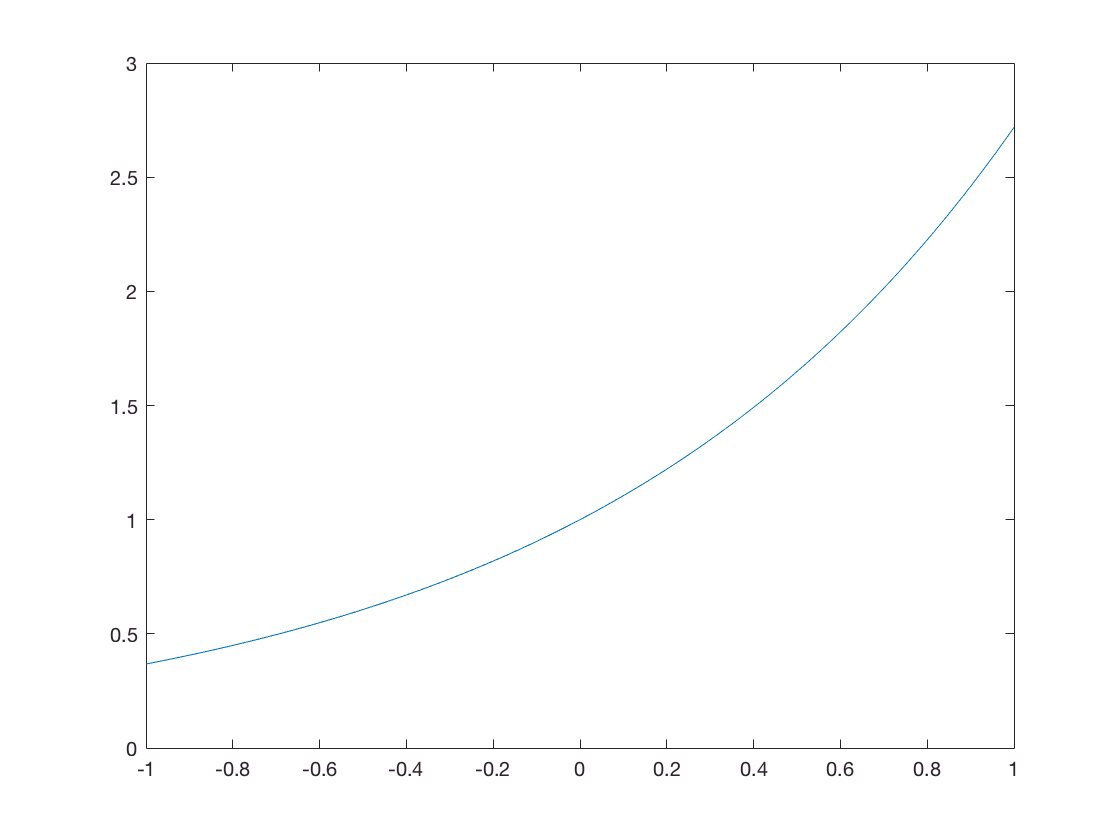

x = linspace(-1,1,100);
y = myfun1(x);
plot(x,y)

Now let's consider a more general exponential function, that depends on a parameter k, namely y = exp(kx). At the end of this script you will find a new function **myfun2** that accepts k and x as input arguments and returns the value of the function as an output. Let's first evaluate it and plot it with k=1, which should give us the same curve as before. Notice that we redefine x: we don't have to because it already exists, but it doesn't hurt at this stage.

x = linspace(-1,1,100);
k = 1;
y = myfun2(k,x);
plot(x,y)

We can now visualize this curve with different values of k, e.g. k=1 and k = 2.

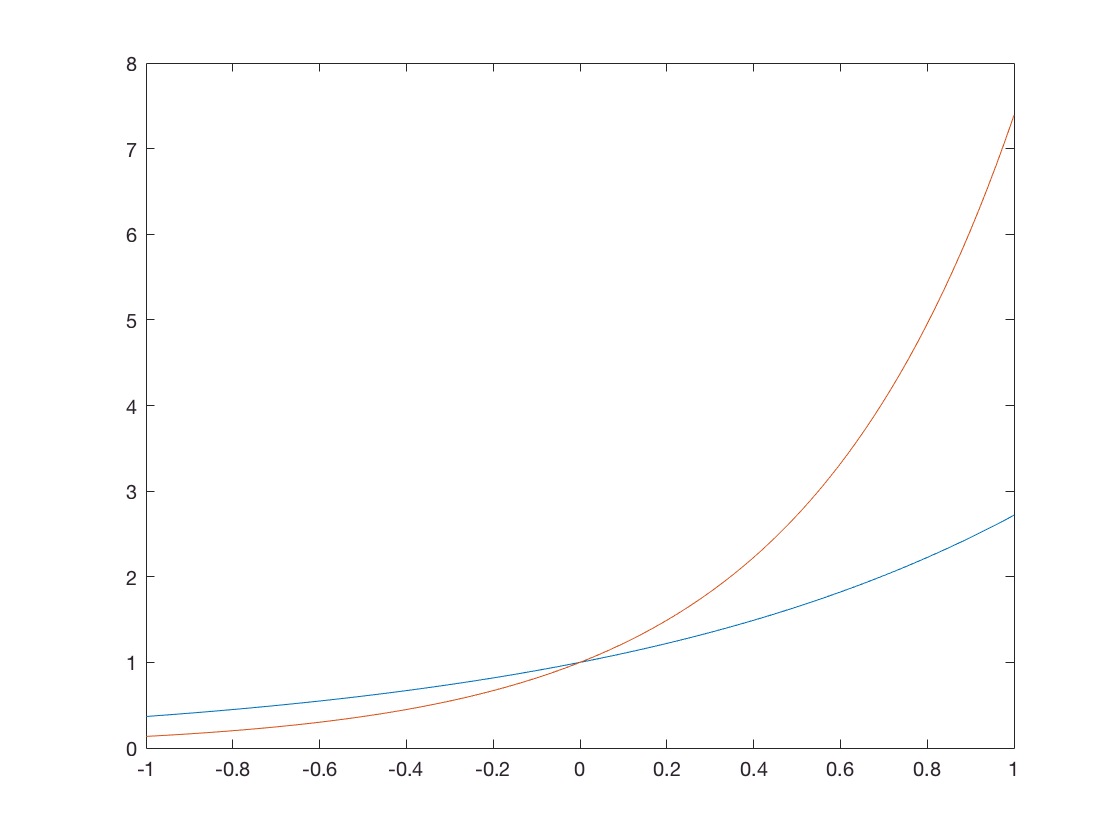

x = linspace(-1,1,100);
k = 1;
y = myfun2(k,x);
plot(x,y)
hold on
k = 2;
y = myfun2(k,x);
plot(x,y)
hold off

We see both curves now, and the curve with k=2 increases faster as we increase x. What if we wanted to run through lots of k values? We can use a **for** loop

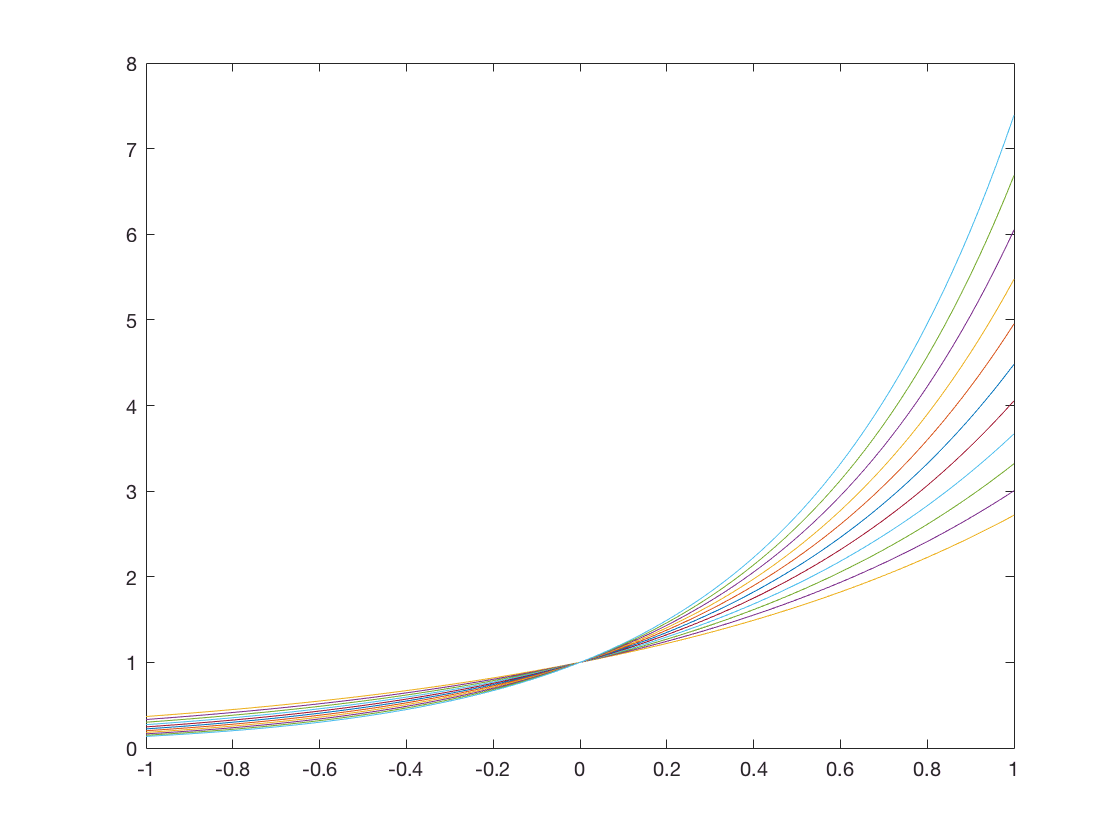

x = linspace(-1,1,100);
hold on
for k = 1:0.1:2
    y = myfun2(k,x);
    plot(x,y)
end
hold off

function res = myfun1(x)
    res = exp(x);
end

function res = myfun2(k,x)
    res = exp(k.*x);
end